# DRTS Mini project: Canbus

This is documentation of mini project from the course Distributed Real-Time Systems.

## Assignment task 1: 

### - Create a DNC/RTC arrival-model of the periodic external traffic sources of the in-car network (choose arrival curve types and determine parameters)

Of the periodic external traffic sources there are four wheel sensors and one ESP sensor. The arrival curve is chosen to be of the affine type. The parameters of the external sources are defined in the script below. The periodic external traffic sources will be defined in the following order. 

- Arrival curve for one wheel sensor

- Arrival curve for the 4 wheel sensors combined

- Arrival curve for ESP 

- Combination of all periodic sources in one arrival curve

clc;clear;close all;

BW = 1*10^3; % [bpms] Serialization speed ms = miliseconds

% ======================= Wheel sensor parameters =======================
N_W = 4;		% Amount of wheel sensors   
p_W = 20;		% Amount of bits per sensor per period
O = 0;			% Overhead
T = 10;			% Transfer period for both wheel sensor and ESP [ms]

n = 1;			% Amount of sensor packets in each dataframe (CAN packet)
k_W = p_W*n+O;	% Bits per packet
tau = 0;		% jitter

% Arrival curve - One wheel sensor:
r_W = k_W/(n*T);					% Rate
b_W = k_W * (tau/T + 1);			% Burst
arr_W = rtccurve([0, b_W, r_W]);	% Arrival curve definition 


The arrival curve of the one wheel sensor is plotted below in Figure 1

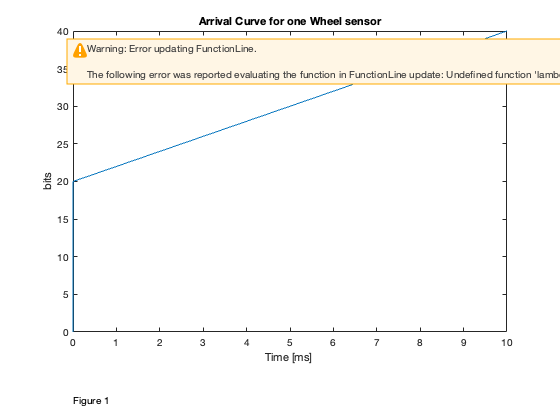

figure(1)
rtcplot(arr_W,T)
title('Arrival Curve for one Wheel sensor')
xlab = sprintf('Time [ms] \n\n\n\n');
xlabel(xlab)
text(0,-9,'Figure 1')
ylabel('bits')

The 4 wheel sensors are joined into one arrival curve

% Arrival curve - All wheel sensors
r_W_all = N_W*r_W;								% Rate
b_W_all = N_W*b_W;								% Burst
arr_W_all = rtccurve([0, b_W_all, r_W_all]);	% Arrival curve definition 

The arrival curve of the 4 joined wheel sensor is plotted below in Figure 2

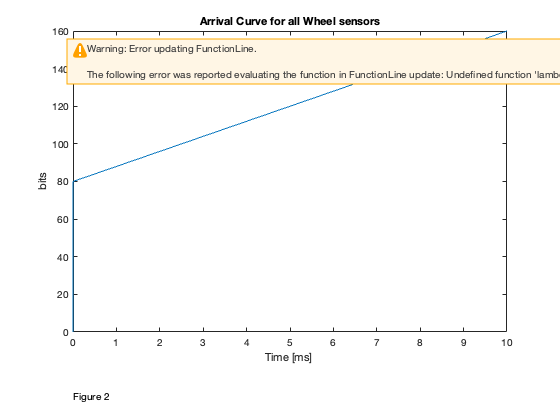

figure(2)
rtcplot(arr_W_all,T)
title('Arrival Curve for all Wheel sensors')
xlabel(xlab)
text(0,-34,"Figure 2")
ylabel('bits')

Next up is the arrival curve of the ESP sensor, it is defined as follows

% Arrival curve - ESP sensor
p_ESP = 8;			% Amount of bits per sensor per period
k_ESP = p_ESP+O;	% Bits per period, including overhead

% Arrival:	
r_ESP = k_ESP/(n*T);					% Rate
b_ESP = k_ESP * (tau/T + 1);			% Burst
arr_ESP = rtccurve([0, b_ESP, r_ESP]);	% Arrival curve definition 

The arrival curve of the ESP sensor is plotted below in Figure 3

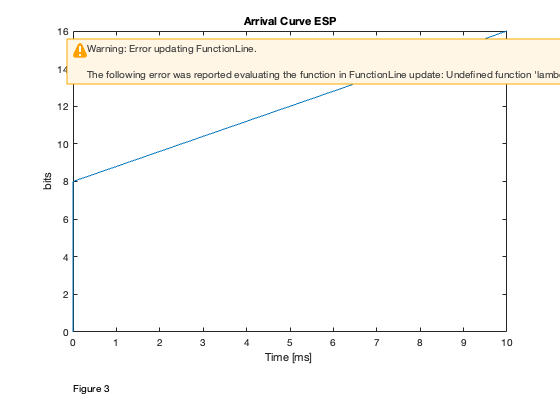

figure(3)
rtcplot(arr_ESP,T)
title('Arrival Curve ESP')
xlabel(xlab)
text(0,-3,"Figure 3")
ylabel('bits') 

As a last resort, the 4 Wheel sensors and the ESP is combined to create one arrival for all periodic traffic sources.

% Combination of periodic arrival constraints:
r_per = r_W_all + r_ESP;	% All periodic rate
b_per = b_W_all + b_ESP;	% All periodic burst

The arrival curve of all periodic traffic sources is plotted below in Figure 4

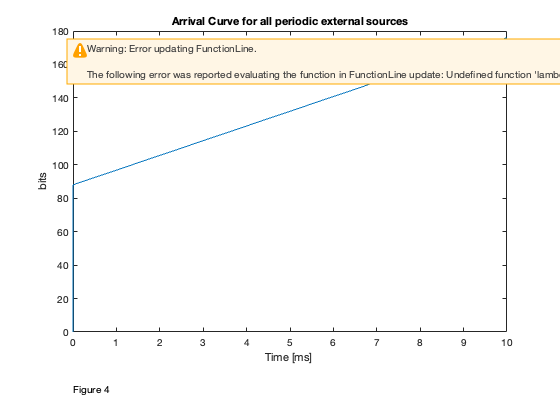

figure(4)
arr_per = rtccurve([0, b_per, r_per]);	 % Periodic sources arrival curve
rtcplot(arr_per, T)
title('Arrival Curve for all periodic external sources')
xlabel(xlab)
text(0,-34,"Figure 4")
ylabel('bits')

As seen in Figure 4, the burst is 88 corresponding to one packet from each periodic traffic source (4*20 + 8). The rate of the periodic sources is 8.8/ms, corresponding to the 88 bits/10 ms.

### - Create a DNC/RTC model for your communication network (Identify network elements, select curve types and parameters)

There is one network element i our communication network, nemely the CANbus interface. A service curve is defined.

Service curve rate is set a 5% lower than bandwidth to ensure we're not marginally stable.

% Service curves:
d = (n-1)*T; % Delay - 0 since we are not packing more than one sensor
serv = rtccurve([d, 0, BW*0.95]);

The service curve of the CANbus is plotted below in Figure 5

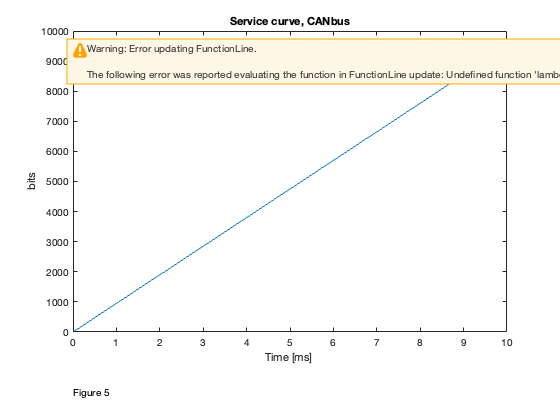

figure(5)
rtcplot(serv,T)
title('Service curve, CANbus')
xlabel(xlab)
text(0,-2000,"Figure 5")
ylabel('bits')

The service curve of the CANbus is not plotted with the arrival curve of the periodic traffic sources, along with the maximum backlog and delay. This can be seen below in Figure 6

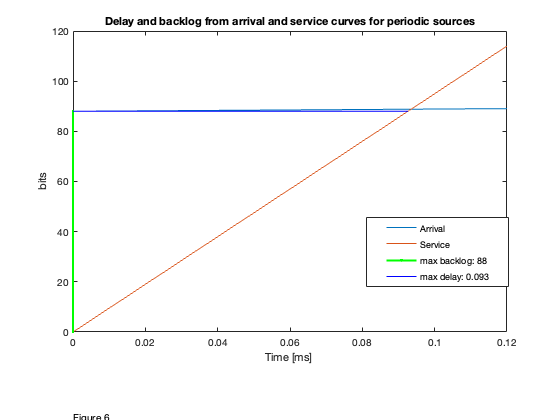

% Backlog and delay of periodic sources:
figure(6)
rtcplot(arr_per, 0.12) % Plot Arrival curve
hold on
rtcplot(serv) % Service curve
rtcplotv(arr_per,serv) % Backlog
rtcploth(arr_per,serv, 'b') % Delay
title('Delay and backlog from arrival and service curves for periodic sources')
xlabel(xlab), text(0,-34,"Figure 6")
ylabel('bits')

delay = rtch(arr_per,serv); backlog = rtcv(arr_per,serv);
str_delay = sprintf('max delay: %0.3f', delay);
str_backlog = sprintf('max backlog: %d', backlog);
legend('Arrival', 'Service', str_backlog, str_delay)

legend('Position',[0.65417,0.3177,0.25536,0.16548])

The maximum possible backlog is 88 bits, with a corresponding maximum delay of 0.093 ms

### - Guess initial parameters for token bucket filters (for the Poisson traffic sources) and include parameters in the DNC/RTC model.

% - Packet size is defined in task as 1400 bits
% - Average period is set to 30 ms (although its a poisson process)

% Rear Camera parameters
T_RC = 40;		% [ms]
p_RC = 1400;	% Packet size - Number of bits per packet

% Multimedia parameters
T_MM = 40;		% [ms]
p_MM = 1400;	% Packet size - Number of bits per packet

% Token bucket filter parameters - initial guesses
M_TB = 5;		% Bucket size - Burst parameter (random guess=
T_TB = 30;		% [ms] Token replenishment rate - Curve rate (faster than 40ms)



### - Determine arrival curves for outputs of token bucket filters and include in the DNC/RTC model.

% Arrival curve Rear Camera
r_RC = 1/T_TB * p_RC;
b_RC= p_RC * M_TB;
arr_RC = rtccurve([0, b_RC, r_RC]);

The arrival curve of the rear camera is plotted in Figure 7

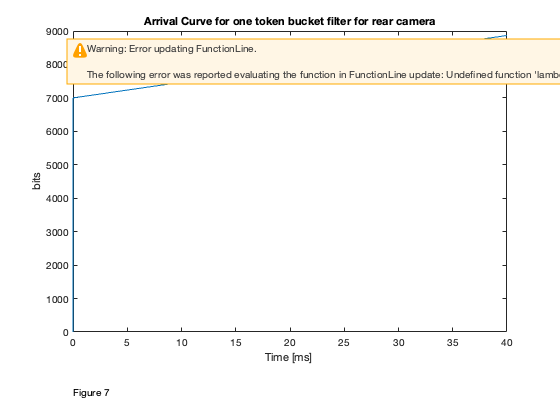

figure(7)
rtcplot(arr_RC, T_RC)
title('Arrival Curve for one token bucket filter for rear camera')
xlabel(xlab), text(0,-1800,"Figure 7")
ylabel('bits')

% Arrival curve Multi-media
r_MM = 1/T_TB * p_MM;
b_MM= p_MM * M_TB;
arr_MM = rtccurve([0, b_MM, r_MM]);

The arrival curve of the multi media is plotted in Figure 8

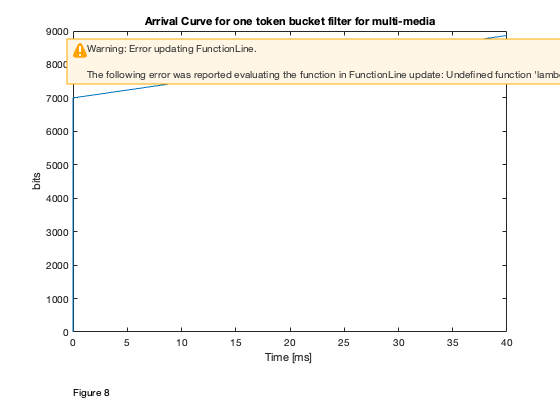

figure(8)
rtcplot(arr_MM, T_MM)
title('Arrival Curve for one token bucket filter for multi-media')
xlabel(xlab), text(0,-1800,"Figure 8")
ylabel('bits')

The arrival curves of the multi media and rear camera is combined into one arrival curve:

arr_TB_tot = rtcplus(arr_RC, arr_MM);

The combined arrival curves of the rear camera and multi media is plotted in Figure 9

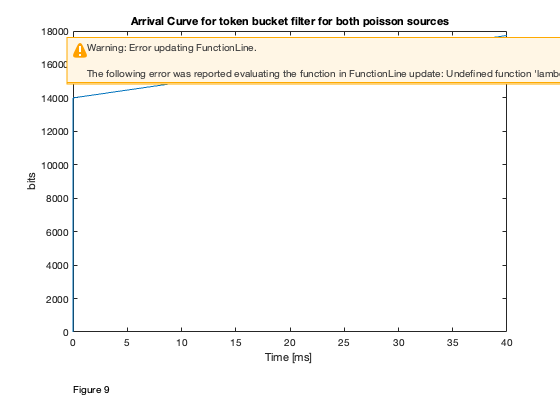

figure(9)
rtcplot(arr_TB_tot, T_MM)
title('Arrival Curve for token bucket filter for both poisson sources')
xlabel(xlab), text(0,-3400,"Figure 9")
ylabel('bits')

### - Compute max backlogs and max waiting times for all flows for the (non)deterministic part of the network

The arrival curves of both the periodic (Wheel sensor and ESP) and token bucket (Rear camera and multi media) sources are combined

% Arrival curve: All external network sources (periodic and poisson)
arr_all = rtcplus(arr_per, arr_TB_tot);


Backlog and delay is computed and plotted from combined arrival curve of all the sources along with the service curve of the CANbus network, in Figure 10

% Backlog and delay:
figure(10)
rtcplot(arr_all, 20) % Plot Arrival curve
hold on
rtcplot(serv) % Service curve
rtcplotv(arr_all,serv) % Backlog
rtcploth(arr_all,serv, 'b') % Delay
title('Delay and backlog from arrival and service curves of all external sources')
xlabel(xlab), text(0,-3400,"Figure 10")
ylabel('bits')

delay = rtch(arr_all,serv), backlog = rtcv(arr_all,serv)

delay = 14.8295

backlog = 14088

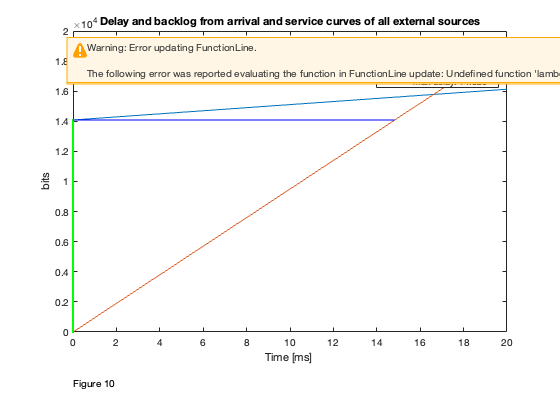

str_delay = sprintf('max delay: %0.3f', delay);
str_backlog = sprintf('max backlog: %d', backlog);
legend('Arrival', 'Service', str_backlog, str_delay)

### - Encode the network model in TrueTime.

The network is implemented in TrueTime as follows in Figure 11

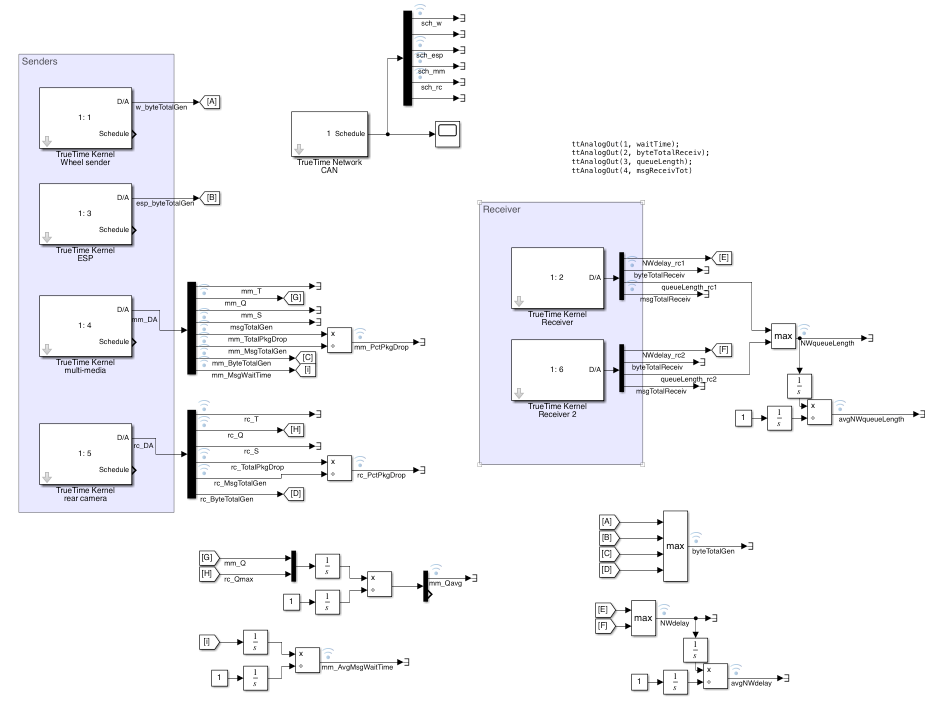

*Figure 11: TrueTime network model*

### - Simulate with TrueTime to obtain estimates of mean and max queue lengths as well as mean and max waiting times.

All of the simulated values for queue length and waiting times are obtained from a simulation of 100 seconds. The values are only from the canbus network and does not include the queue and delays from the token bucket filters. These will be considered individually in assignment task 3.

The queue length development during 100 seconds of simulation can be seen in Figure 12 below. The maximum queue length can be observed to be a little less that 10000 bits. This compares with a maximum theoretical backlog from the RTC model of 14088.

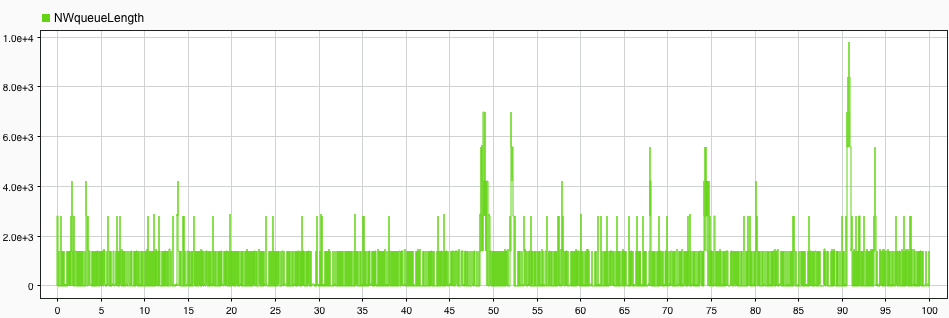

*Figure 12: Network queue length development over 100 sec.*

The average queue length convergence can be seen in Figure 13 below. The average seems to converge somewhere around 250 bits.

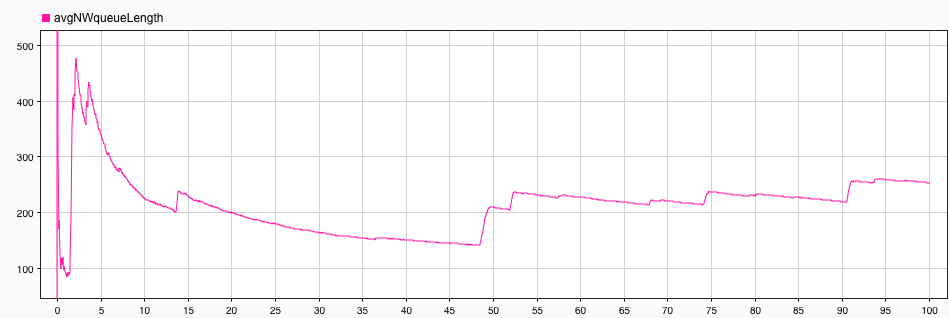

*Figure 13: Network queue length average development over 100 sec.*

The waiting time of the development during 100 seconds of simulation can be seen in Figure 14 below. The maximum delay can be observe to be about 4.2 ms. This compares with a theoretical maximum delay from the RTC model of 14.829 ms.

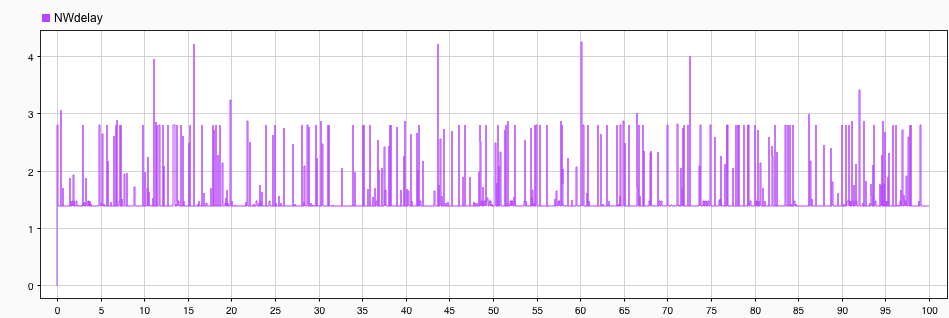

*Figure 14: Network delay development over 100 sec. *

The average delay convergence can be seen in Figure 15 below. The average seems to converge somewhere around 1.47 ms.

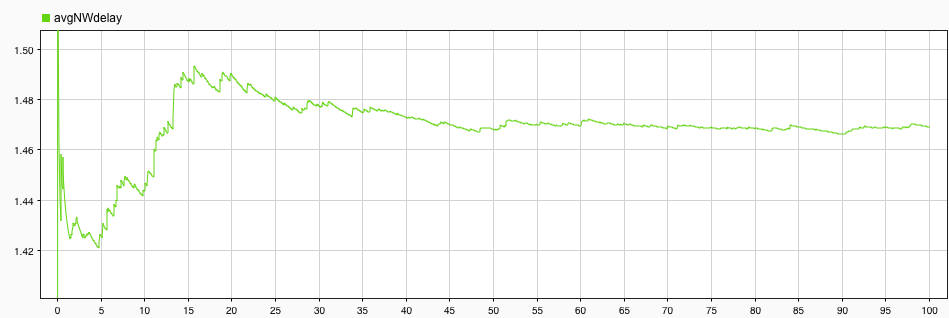

Figure 15: Network average delay development over 100 sec.

## Assignment task 3

### - Select a suitable queueing model for Token Bucket input queues

To accommodate a finite queue (buffer) length, the M/M/1/L is chosen as a probabilistic model for the Token Bucket Filter.

### - Compute mean queue lengths, mean waiting times and packet drop probabilities for input queues.

The M/M/1/L queue can be characterised in steady state based on their parameters $\lambda$(arrival intensity), $\mu$(service intensity), and a utilisation parameter $\rho =\frac{\lambda }{\mu }\;$

The token bucket filters implemented in the simulation have the same parameters:


$$\begin{array}{l}
\lambda =\frac{1}{40\;\textrm{ms}}\;\\
\mu =\frac{1}{30\;\textrm{ms}}\\
\rho =\frac{\lambda }{\mu \;}=\frac{30}{40}=0\ldotp 75\\

\end{array}$$


lambda = 1/(T_RC*1e-3);	mu = 1/(T_TB*1e-3);
rho = lambda/mu;
L = 6;	% Queue size

The mean queue length can be obtained by the expression


$$\begin{array}{l}
E\left\lbrack Q\right\rbrack =\frac{\rho }{\left(1-\rho^{L+1} \right)\left(1-\rho \right)}\\
\;
\end{array}$$


EQ = rho / ( (1-rho^(L+1)) * (1-rho) )

EQ = 3.4621

The mean waiting time can be obtained by the expression

$E\left\lbrack T\right\rbrack =\frac{1}{\mu }\left(E\left\lbrack Q\right\rbrack +1\right)$ % the one is here as the new arrival to show the delay..

ET = (1/mu) * (EQ + 1) 

ET = 0.1339

The probability of package loss can be obtained by the expression


$$P_{\textrm{Loss}} =\frac{\rho^L -\rho^{L+1} }{1-\rho^{L+1} }$$


P_loss = (rho^L-rho^(L+1)) / (1-rho^(L+1))

P_loss = 0.0513

### - Compare results with simulated and measured results from previous assignments

We will include some extra data from the simulation in this section to account for the queue and delays seperately of the token bucket filter of one source: namely multi media. We consider the sizes of the queue be in the unit packets, where we assume they are of size 1400 bits.

The average queue length of the token bucket for the multi media can be seen in Figure 16. The average queue converges around 0.07 packets, compared with an expected queue length from the M/M/M/L model of 3.46 packets. 

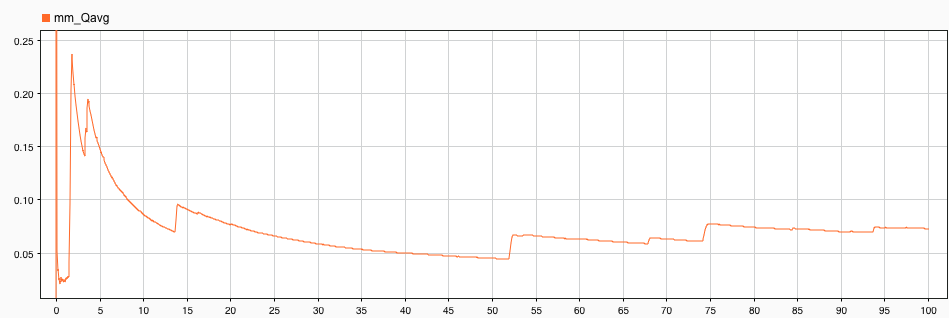

*Figure 16: Average queue in token bucket filter for multi media in packets. *

The average delay of the token bucket for the multi media can be seen in Figure 17. The average delay converges around 0.043 ms compared with expected delay of 0.134 ms from the M/M/M/L model.

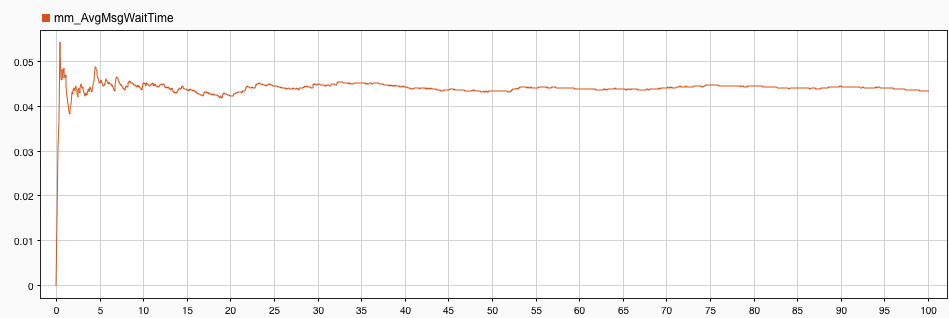

*Figure 17: Average delay in token bucket filter for multi media in [ms].*

The loss proportion during the 100 sec. simulation for the token bucket filter can be seen in Figure 18. However, as it is zero during the entire simulation, it makes sense to investigate the development of the queue, to confirm that the package drop/loss percentage is evaluated correctly.

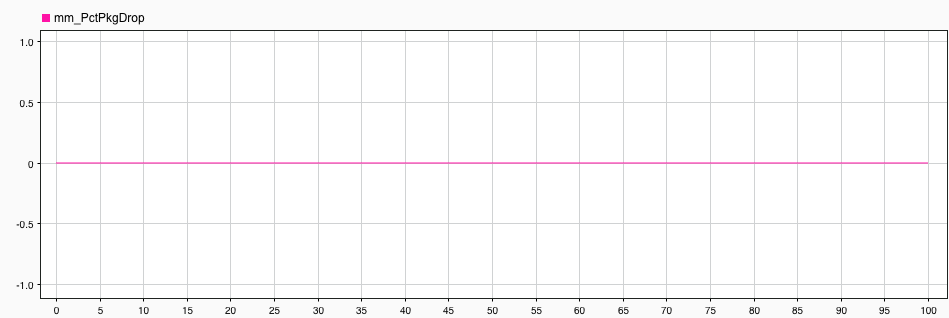

*Figure 18: Loss proportion for the token buket filter for the multi media in absolute terms.*

The queue evolvement during the 100 seconds can be observed in Figure 19. Here we see that the queue newer surpasses 5, and as the Queue size is 6, no packet losses are appearing. Thus, we conclude that the zero loss proportion is correct. However, this compares with a probability of loss for the M/M/1/L model of 0.0513 

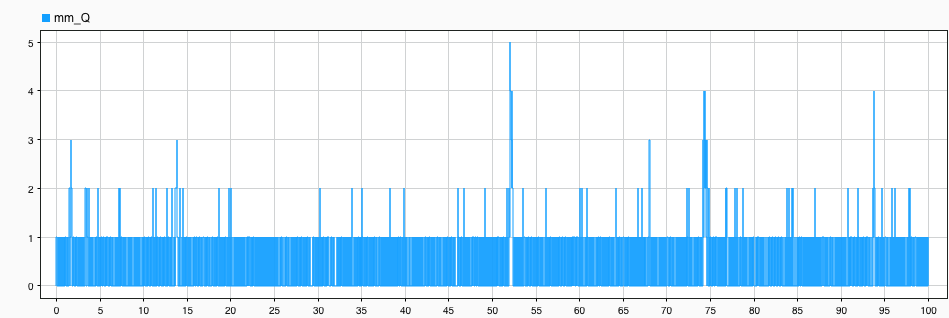

*Figure 19: Queue evolvement during the 100 seconds simulation for the token bucket filter of the multimedia in packets.*

## Assignment task 4

### - Identify safety critical components in the car network.

All the components that we cover in this network architecture includes: 

- CANbus

- Wheel sensors measuring position for ABS and EPS

- EPS: Electronic stability controller

- EC: Engine controller

- HUD: Head up display

- MM: Multimedia system

- RC: Rear camera

Out of these components the HUD, MM and RC are not considered safety critical. 

The CANbus and the wheel sensors enables communication and measurement for safety critical functions as ABS and EPS.

The EPS is a stability controller itself, which is highly safety critical as it reduces the risk of unstable driving.

The engine controller allows confident controls of the engine and hence the car speed and acceleration - a fail in engine controller can lead to dangerous situations, especially for travel on e.g. steep roads and highways.

#### - Assume every component fails with a failure rate 0.5 h-1. (0.5e-6 h^-1)

 To relate $0\ldotp 5\cdot {10}^{-6} \cdot h^{-1}$ we transform it from hours to years.

lambda_h = 0.5e-6;

lambda_h = 5.0000e-07

T_h = 1/lambda_h

T_h = 2000000

T_y = T_h /(365*24)

T_y = 228.3105

lambda_y = 1/T_y

lambda_y = 0.0044

#### - Compute the safety related failure rate for the car as a whole.

It is assumed that all of the safety critical components need to function in order for the car to be functional. Therefore the reliability is calculated as a serial connection

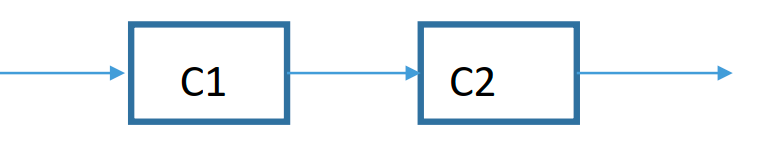


$$R\left(t\right)=R_1 \left(t\right)\cdot R_2 \left(t\right)\cdot R_3 \left(t\right)$$


Assuming exponential timers:


$$R\left(t\right)=\exp \left(-\lambda_1 \cdot \;t\right)\exp \left(-\lambda_2 \cdot \;t\right)\ldotp \ldotp \ldotp \exp \left(-\lambda_N \cdot \;t\right)=\exp \left(-\left(\lambda_1 +\lambda_2 +\ldotp \ldotp \ldotp \lambda_N \right)\cdot \;t\right)$$


Therefore the rates are added.

There are 7 safety critical components and the failure rate is $0\ldotp 5\cdot \;{10}^{-6} \cdot \frac{1}{h}$

All components:


$$0\ldotp 5*{10}^{-6} \cdot h^{-1} \cdot 7=3\ldotp 5\cdot \frac{1}{\left(h\cdot {10}^6 \right)}$$


lambda_h_all = 7 * 0.5e-6 %

lambda_h_all = 3.5000e-06

T_h_all = 1/lambda_h_all

T_h_all = 2.8571e+05

T_y_all = T_h_all /(365*24)

T_y_all = 32.6158

lambda_y_all = 1/T_y_all

lambda_y_all = 0.0307

#### - Compute the probability that a safety related fault has appeared before the car is 10 years old.

The reliability and fault probability functions are defined:

F_tau = @(t) 1 - exp(-lambda_y_all*t);
Rt = @(t) 1 - F_tau(t);

The probability of a fault occuring within 10 years is evaluated using the expression above

Prob_10years = F_tau(10)

Prob_10years = 0.2641

The probability of a fault occuring within 10 years is 26.4 %.

Below the fault probability is plotted with respect to time

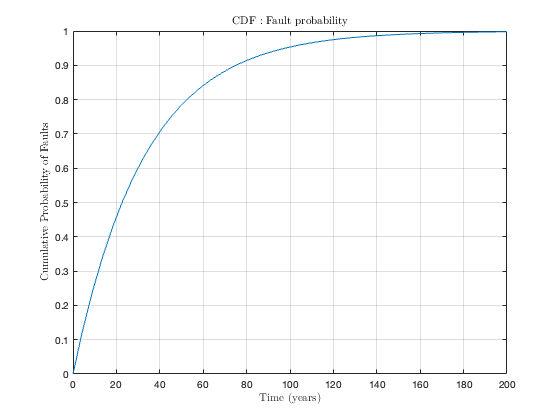

figure
fplot(@(t) F_tau(t), [0 200])
grid on
xlabel('Time (years)', 'Interpreter', 'latex')
ylabel('Cumulative Probability of Faults', 'Interpreter', 'latex')
title('CDF : Fault probability', 'Interpreter', 'latex')

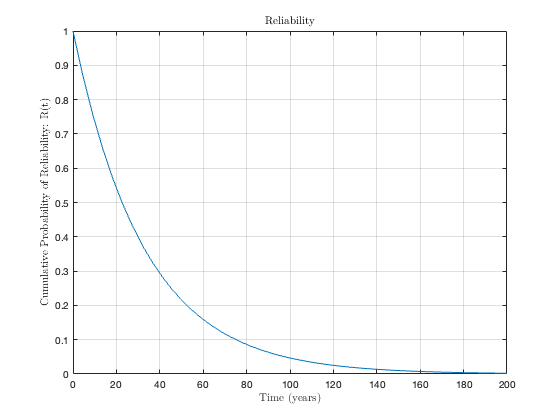



figure
fplot(@(t) Rt(t))
xlim([0 200])
grid on
xlabel('Time (years)', 'Interpreter', 'latex')
ylabel('Cumulative Probability of Reliability: R(t)', 'Interpreter', 'latex')
title('Reliability', 'Interpreter', 'latex')

#### - Suggest a redundancy architecture to improve failure rate.

In this simple case where all components fail with the same failure rate there is no incentive to differentiate between components with regards to redundance. An obvious way to increase reliability is to couple an extra component in parallel at every component. A diagram of this structure can be seen below:

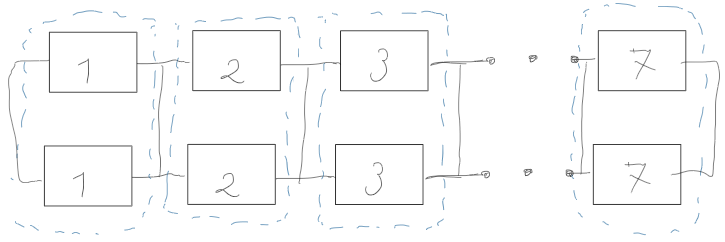

Figure XX: Redundancy Architecture 1. Any combination where at least one of each component is ok means the system is working.

Intuitively the above structure seems like a better option than the below structure where a copy of the first serial connection of components is simply connected in parallel at both ends. We here consider the 7 serial connected components as one component and then parallel couple two of those. To confirm this intuition, the failure rate is calculated for both topologies.

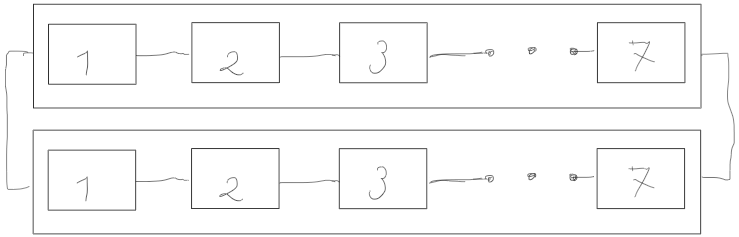

Figure XX: Redundancy Architecture 2. If all subcomponent in at least one of the parallel components work, the systems is working. 

#### - Compute the (time dependent) failure rate for the redundancy architecture.

*Redundancy Architecture 1:* 

% Redundancy architecture #1
lambda_y_parallel_single = @(t) 2 * lambda_y *( exp(lambda_y*t) -1 ) / ( 2*exp(lambda_y*t) - 1 )

lambda_y_parallel_single = function_handle with value:
    @(t)2*lambda_y*(exp(lambda_y*t)-1)/(2*exp(lambda_y*t)-1)


lambda_y_redund_1 = @(t) lambda_y_parallel_single(t) * 7

lambda_y_redund_1 = function_handle with value:
    @(t)lambda_y_parallel_single(t)*7


% Plotting figure
figure
fplot(@(t) lambda_y_redund_1(t), [0 100])

grid on
xlabel('Time (years)', 'Interpreter', 'latex')
ylabel('Failure rate $\lambda(t)$ $\left[\frac{1}{year}\right]$', 'Interpreter', 'latex')
title('Time dependent failure rate for two parallel connected components', 'Interpreter', 'latex')


*Redundancy Architecture 2:* 

% Redundancy architecture #2
lambda_y_redund_2 = @(t) 2 * lambda_y_all *( exp(lambda_y_all*t) -1 ) / ( 2*exp(lambda_y_all*t) - 1 )

lambda_y_redund_2 = function_handle with value:
    @(t)2*lambda_y_all*(exp(lambda_y_all*t)-1)/(2*exp(lambda_y_all*t)-1)



% Plotting with previous figure
hold on
fplot(@(t) lambda_y_redund_2(t), [0 100])

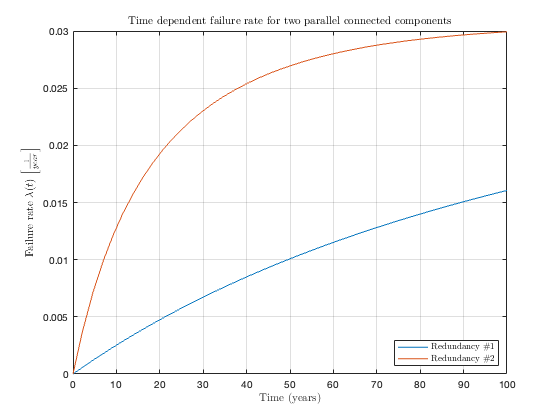

legend('Redundancy \#1','Redundancy \#2', 'Interpreter', 'latex','Location','southeast')

#### - Compute the probability that a safety related fault has appeared before the car is 10 years old (for the redundancy architecture).

Firstly the reliability function is calculated symbolically and plotted

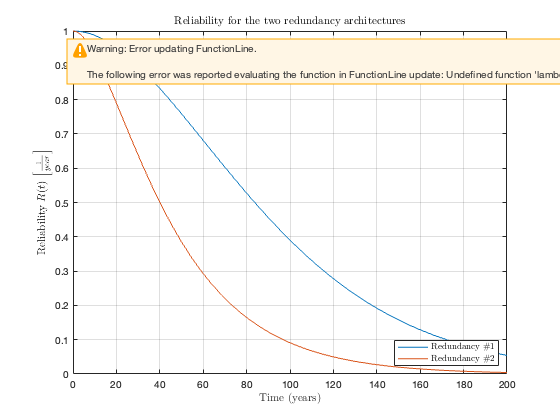

% Reliability
% ------------------------------------

% Architecture #1
syms t
% Symbolic version
lambda_y_redund_1_sym = 2 * lambda_y *( exp(lambda_y*t) -1 ) / ( 2*exp(lambda_y*t) - 1 ) * 7;

R_redund_1 = exp(-1*int(lambda_y_redund_1_sym));


% Architecture #2
syms t
% Symbolic version
lambda_y_redund_2_sym = 2 * lambda_y_all *( exp(lambda_y_all*t) -1 ) / ( 2*exp(lambda_y_all*t) - 1 );

R_redund_2 = exp(-1*int(lambda_y_redund_2_sym));


% Plotting
figure
fplot(R_redund_1)
xlim([0 200])
hold on
fplot(R_redund_2, [0 200])
grid on
xlabel('Time (years)', 'Interpreter', 'latex')
ylabel('Reliability $R(t)$ $\left[\frac{1}{year}\right]$', 'Interpreter', 'latex')
title('Reliability for the two redundancy architectures', 'Interpreter', 'latex')
legend('Redundancy \#1','Redundancy \#2', 'Interpreter', 'latex','Location','southeast')

Secondly the fault probability function is calculated from the Reliability function. From the fault probability function the probability of a fault occuring within 10 years is calculated


% Fault probability
% ------------------------------------

% Architecture #1
F_redund_1 = 1-R_redund_1;
t = 10;

% Probability for a fault before 10 years
Prob_redund_1_10years = double(subs(F_redund_1))

Prob_redund_1_10years = 0.0128


% Architecture #2
F_redund_2 = 1-R_redund_2;

% Probability for a fault before 10 years
Prob_redund_2_10years = double(subs(F_redund_2))

Prob_redund_2_10years = 0.0697

The probability of a fault within 10 years without the redundency architecture is: 26.4 %

The probability of a fault within 10 years with redundency architecture #1 is: 1.28 %

The probability of a fault within 10 years with redundency architecture #2 is: 6.97 %

Below can be seen the fault probabilities plotted for respectively the original system, and with the two redundancy architectures.

Redundancy architecture #1 ends up showing superior fault probability, which supports our intuition that the it makes more sense to allow all combinations of subcomponents (Redundancy Architecture #1) than to only allow two combinations of subcomponents (Redundancy Architecture #2).

Both architecture drasticly performs the fault probability, but Redundancy Architecture #1 is definitely the better one. This is confirmed in the below plot for all time.

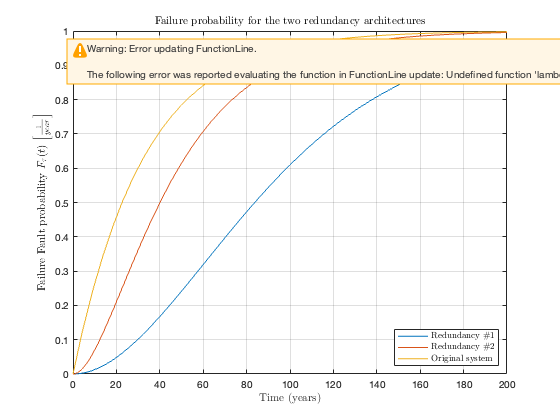


% Plotting fault probability as function of time
figure
fplot(F_redund_1, [0 200])
hold on
fplot(F_redund_2, [0 200])
grid on
fplot(@(t) F_tau(t), [0 200])
xlabel('Time (years)', 'Interpreter', 'latex')
ylabel('Failure Fault probability $F_\tau(t)$ $\left[\frac{1}{year}\right]$', 'Interpreter', 'latex')
title('Failure probability for the two redundancy architectures', 'Interpreter', 'latex')
legend('Redundancy \#1','Redundancy \#2', 'Original system', 'Interpreter', 'latex', 'Location','southeast')